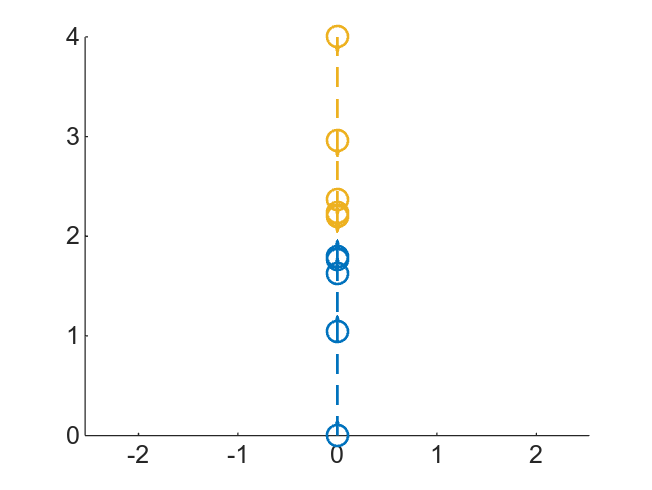

clear, clc, close all

% stable and unstable equibilim points problem
car1 = carModel(0,0,pi/2+0.001,[0,4,pi]);
car2 = carModel(0,4,-pi/2,[0,0,0]);

for i = 1:1000
    [v_nominal1, omega_nominal1] = car1.getPcontrol();
    V_filtered1 = car1.RCBF_Filter(car2,[v_nominal1; omega_nominal1]);

    [v_nominal2, omega_nominal2] = car2.getPcontrol();
    V_filtered2 = car2.RCBF_Filter(car1,[v_nominal2; omega_nominal2]);

    car1.updateState(V_filtered1);
    car2.updateState(V_filtered2);
end

figure
hold on
car1.plotHistory()
car2.plotHistory()
axis equal
hold off

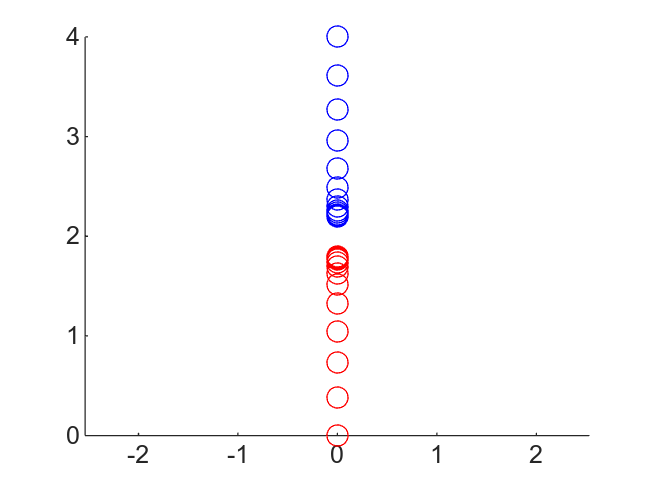


figure
hold on
stepInterval = 10;
for i = 1:stepInterval:length(car1.history)-1
    plot(car1.history(i,1), car1.history(i,2),"LineStyle","none","Marker","o","MarkerSize",8, "Color","red")
    plot(car2.history(i,1), car2.history(i,2),"LineStyle","none","Marker","o","MarkerSize",8, "Color","blue")
    axis equal
    pause(0.1)
end
hold off